% first time using matlab; am refrencing a lot of external sources; am trying
% to keep the code origional

[data, fs] = audioread("./noisyaudio-1.mp4");

% my dft code translated from C++
% works but runs terribly so I use the built in fft function instead
%{
n = length(data)
data_dft = zeros(n,1)
for k = 1:n
    for j = 1:n
        data_dft(k) = data_dft(k) + data(j) * (cos(-2 * pi * j * k / n) + i * sin(-2 * pi * j * k /n))
    end
end
plot(abs(data_dft(:,1)))
%}


% filter general specifications
pb_attenu_max = 10 ^ (-3/20); % percentage maximum attenuation in passband
sb_attenu_min = 10 ^ (-30/20); % percentage highest retention of stop band signal
wp = 2.0e3 / (fs/2);  % pass frequency as ratio of sampling
ws = 2.5e3 / (fs/2); % stop frequency as ratio of sampling

% intermeidate variables
kp = 1 / (pb_attenu_max ^ 2) - 1

kp = 0.9953

ks = 1 / (sb_attenu_min ^ 2) - 1

ks = 999.0000

op = wp % IIR

op = 0.3628

os = ws 

os = 0.4535

wn = ceil(.5 * log(ks/kp) / log(os/op));  % Nth order to meet band requirement
oc_wp = op / (kp ^ (wn / 2))

oc_wp = 0.3769

oc_ws = os / (kp ^ (wn / 2))

oc_ws = 0.4711


% filter configuration
% = oc_wp to meet stopband requirement
% = oc_ws to meet passband requirement
oc = oc_wp % some value in the range [oc_wp oc_ws]. I couldnt get a slider ui to not look terrible

oc = 0.3769



% filter testing
[nume, denom] = butter(wn, oc)

nume =     0.0000    0.0000    0.0003    0.0014    0.0045    0.0108    0.0198    0.0283    0.0319    0.0283    0.0198    0.0108    0.0045    0.0014    0.0003    0.0000    0.0000


denom =     1.0000   -3.9348    9.1636  -14.7046   17.9367  -17.2286   13.3654   -8.4620    4.3959   -1.8702    0.6472   -0.1797    0.0391   -0.0064    0.0008   -0.0001    0.0000



[H,W] = freqs(nume, denom, 100)

H =    1.1130 + 0.5248i
   1.0957 + 0.5596i
   1.0760 + 0.5963i
   1.0535 + 0.6348i
   1.0278 + 0.6751i
   0.9985 + 0.7171i
   0.9653 + 0.7607i
   0.9275 + 0.8057i
   0.8847 + 0.8519i
   0.8363 + 0.8988i


W =     0.0100
    0.0107
    0.0115
    0.0123
    0.0132
    0.0141
    0.0151
    0.0162
    0.0174
    0.0186


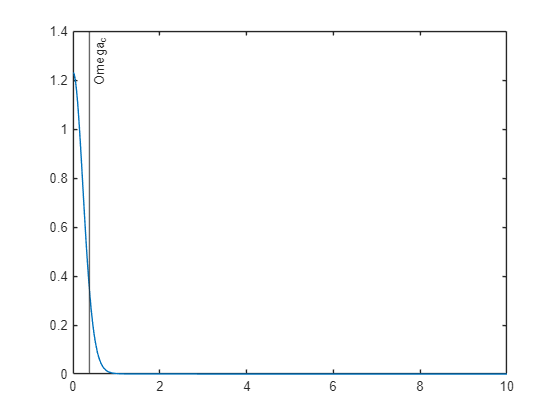

figure(1),plot(W, abs(H))
xline(oc, '-', 'Omega_c')

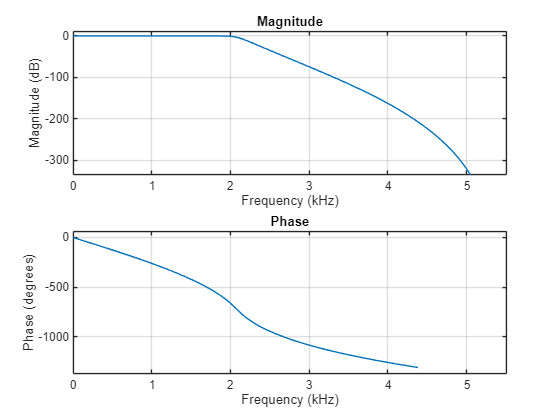


freqz(nume, denom, [], fs);


x = logspace(log10(0.1*2*pi*100), log10(2*pi*fs/2), 1000)

x = 1.0e+04 *

    0.0063    0.0063    0.0064    0.0064    0.0064    0.0065    0.0065    0.0066    0.0066    0.0067    0.0067    0.0067    0.0068    0.0068    0.0069    0.0069    0.0070    0.0070    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0078    0.0078    0.0079    0.0079    0.0080    0.0080    0.0081    0.0081    0.0082    0.0082    0.0083    0.0083    0.0084    0.0085    0.0085    0.0086


oc_rel = oc * pi * fs;
y = 20 * log10(sqrt( 1 ./ ( 1 + (x ./ oc_rel).^(2 * wn) ) ))

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


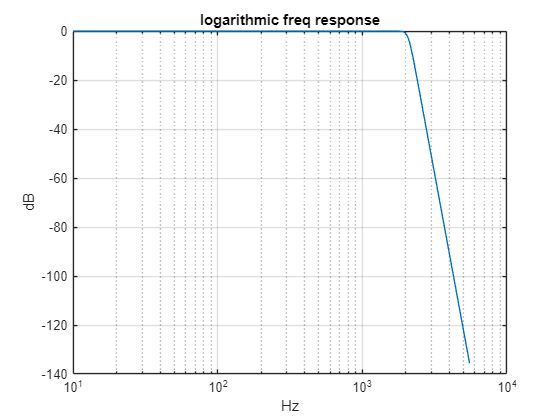


semilogx(x / (2 * pi), y)
ylabel('dB')
xlabel('Hz')
title('logarithmic freq response')
grid on


data_fft = fft(data)

data_fft = 1.0e+02 *

  -4.9967 + 0.0000i
  -0.1849 + 0.0368i
  -0.0478 - 0.1989i
   0.2498 + 0.2678i
   0.0889 - 0.1331i
   0.5691 + 0.0505i
   0.6927 - 0.0607i
  -0.2404 + 0.5618i
   0.5607 - 0.0118i
   0.0963 - 0.5092i


data_filtered = filter(nume, denom, data)

data_filtered =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


data_filtered_fft = fft(data_filtered)

data_filtered_fft = 1.0e+02 *

  -4.9967 + 0.0000i
  -0.1849 + 0.0369i
  -0.0480 - 0.1989i
   0.2501 + 0.2675i
   0.0887 - 0.1332i
   0.5691 + 0.0495i
   0.6926 - 0.0622i
  -0.2390 + 0.5624i
   0.5607 - 0.0134i
   0.0946 - 0.5095i



p = plot(abs(data_fft(:,1)))

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 … ] (1×131473 double)
              YData: [499.6665 18.8485 20.4564 36.6188 16.0090 57.1302 69.5382 61.1105 56.0853 51.8263 12.6197 42.6878 14.3029 15.1156 5.6783 13.8964 35.3879 34.1398 17.9874 7.9991 11.6958 12.3751 17.6560 2.7378 5.9817 13.6270 … ] (1×131473 double)

  Show all propert

p.Color = [0 0 1 0.3]

p =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 … ] (1×131473 double)
              YData: [499.6665 18.8485 20.4564 36.6188 16.0090 57.1302 69.5382 61.1105 56.0853 51.8263 12.6197 42.6878 14.3029 15.1156 5.6783 13.8964 35.3879 34.1398 17.9874 7.9991 11.6958 12.3751 17.6560 2.7378 5.9817 13.6270 … ] (1×131473 double)

  Show all properties


title("input(blue), filtered(red)")
hold on
p = plot(abs(data_filtered_fft(:,1)));
p.Color = [1 0 0 0.3]

p =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 … ] (1×131473 double)
              YData: [499.6672 18.8492 20.4565 36.6183 16.0086 57.1295 69.5375 61.1108 56.0846 51.8261 12.6190 42.6875 14.3032 15.1155 5.6790 13.8966 35.3873 34.1405 17.9870 7.9992 11.6956 12.3756 17.6563 2.7383 5.9816 13.6269 … ] (1×131473 double)

  Show all properties


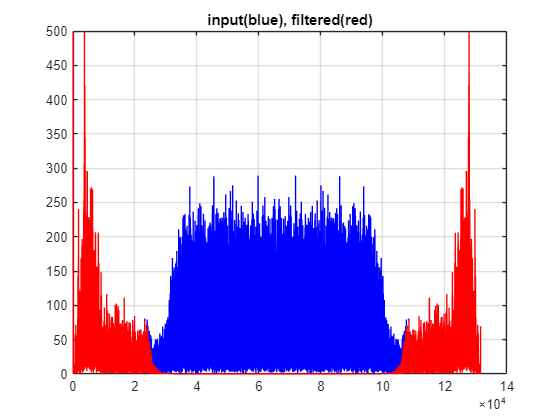

hold off
grid on


% difference equation
fprintf('y[n] = ');

y[n] = 

for i = 1:length(nume)
    if i == 1
        fprintf('%f*x[n]', nume(i));
    else
        fprintf(' + %f*x[n-%d]', nume(i), i-1);
    end
end

0.000002*x[n]

 + 0.000040*x[n-1] + 0.000297*x[n-2] + 0.001387*x[n-3] + 0.004508*x[n-4] + 0.010819*x[n-5] + 0.019834*x[n-6] + 0.028335*x[n-7] + 0.031877*x[n-8] + 0.028335*x[n-9] + 0.019834*x[n-10] + 0.010819*x[n-11] + 0.004508*x[n-12] + 0.001387*x[n-13] + 0.000297*x[n-14] + 0.000040*x[n-15] + 0.000002*x[n-16]

for i = 2:length(denom)
    fprintf(' - %f*y[n-%d]', denom(i), i-1);
end

 - -3.934765*y[n-1] - 9.163560*y[n-2] - -14.704572*y[n-3] - 17.936699*y[n-4] - -17.228558*y[n-5] - 13.365413*y[n-6] - -8.462049*y[n-7] - 4.395889*y[n-8] - -1.870232*y[n-9] - 0.647236*y[n-10] - -0.179690*y[n-11] - 0.039136*y[n-12] - -0.006449*y[n-13] - 0.000757*y[n-14] - -0.000056*y[n-15] - 0.000002*y[n-16]

fprintf('\n');

sound(data_filtered, fs)
audiowrite("./filterednoisyaudio-1.mp4", data_filtered,fs)

Error using audiowrite (line 275)
Unsupported SampleRate value.